# Time evolution for a DAE system on a dumbbell graph

Evolves the basic heat equation through time.

## Set up the graph structure and coordinates of the problem

By default, the discretization type is uniform but you must choose it to be Chebyshev for the time evolution. You can also set other properties such as the number of discretization points per edge.

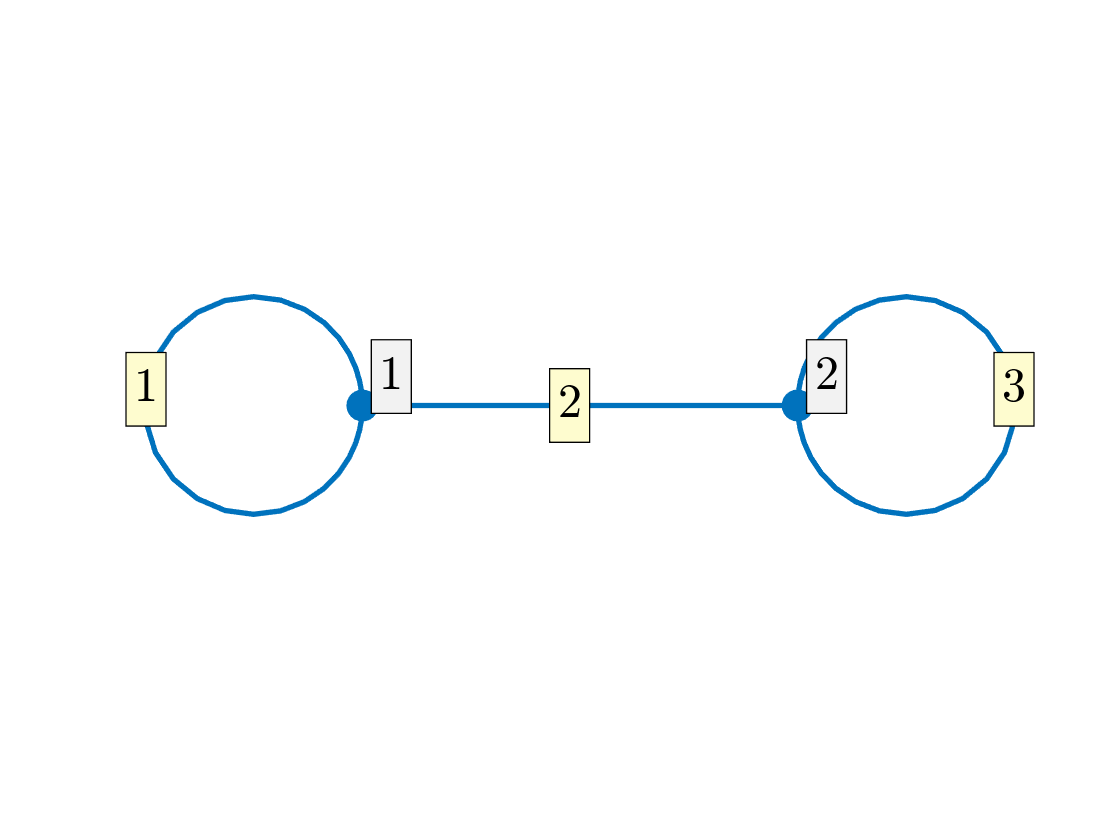

Phi = quantumGraphFromTemplate('dumbbell','discretization','Chebyshev','nX',32);
Phi.plot('layout')

## Define the function

1 = heat

2 = Schrodinger

3 = NLS

type = 2;
f = Phi.myFunc(type);

## Time evolution

You need an initial condition, step size, how long the program should run till and the scheme type you desire. Right now, we have 2nd, 4th and 8th order schemes. For this example, I used an eigenfunction of the stationary problem as an initial condtion.

[evec,eval] = Phi.eigs(8);
j=4;
lambda = eval(j);
u0 = lambda.*evec(:,j);
tend = 1;
[u,t] = Phi.timeEvolveDAEDopri8(f,u0,1e-04,tend,8);

## Plotting the solution

Plotting every piece of information is too much. We'll only plot every ~1000th data point.

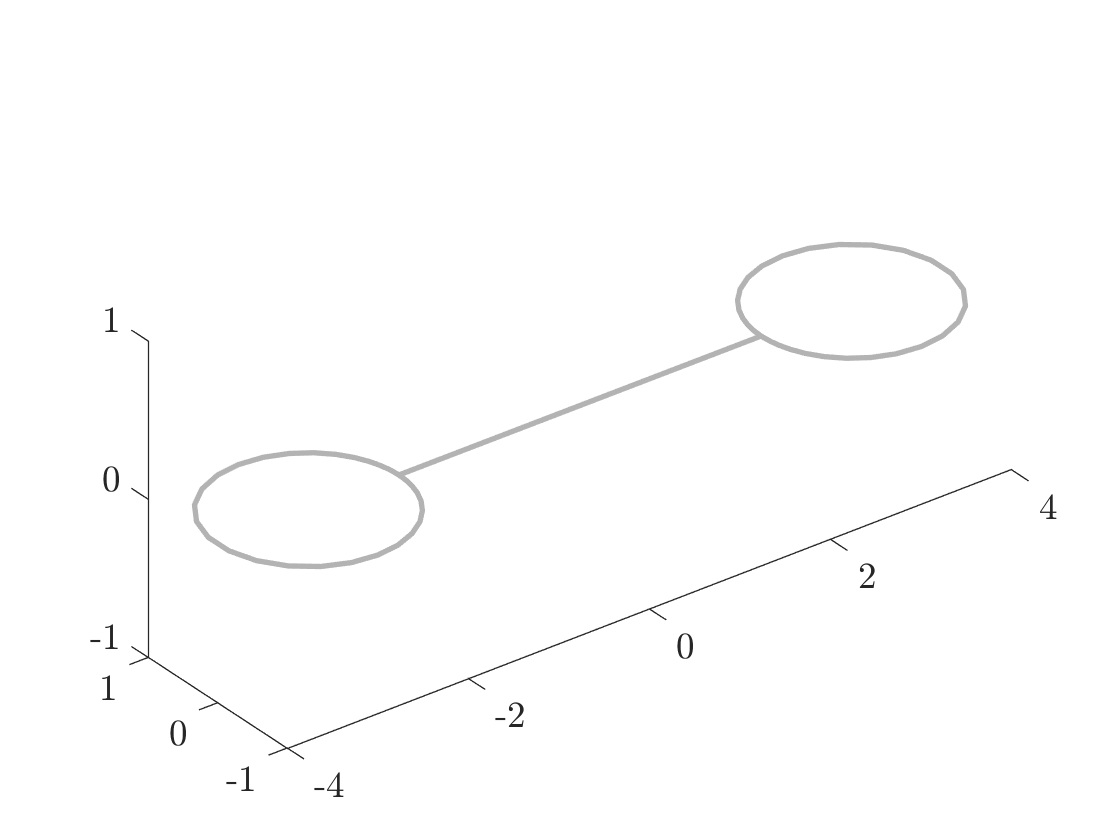

Error using matlab.graphics.axis.Axes/set
Value must be a 1x2 vector of numeric type in which the second element is greater than the first element or is Inf.

Error in quantumGraph/plotOnGraph2D (line 39)
set(gca,'ZLim',[(yMin-yRange/4), (yMax +yRange/4)])

Error in <a href="matlab:matlab.internal.language.introspective.errorDocCallback('quantumGraph/plotOnGraph', 'C:\Users\Shimmer\Documents\GitHub\Quantum-Graphs was working\source\@quantumGraph\plotOnGraph.m', 8)" style="font-weight:

scale = 1000;
for i=1:size(u,2)/scale
    if type == 1
        Phi.plot(u(:,scale*i))
    else
        Phi.plot(abs(u(:,scale*i)).^2)
    end
    title(['t=',num2str(round(t(scale*i),2))])
    axis([-4 4 -1.5 1.5 -.5 .5])
    daspect([1 1 .25])
    xlabel('x')
    ylabel('y')
    zlabel('u')
    pause(.0000000000001)
end

## Error Analysis

We use an analytical solution to 

if type == 1
    uana = @(t) exp(lambda*t).*u0;
else
    uana = @(t) exp(1i*lambda*t).*u0;
end
error = zeros(1,size(u,2));

for i=1:size(u,2)/scale
    error(scale*i) = max(uana(t(scale*i)) - u(:,scale*i));
end

disp('The error is:')
disp(abs(max(error)))
